r = 2.91;
d = 4.86;
init_vector = [r, 0];
vectors = zeros(ceil(d * 10), 2);
theta = asin(0.1/2.91);
rotate_matrix = [cos(theta), -sin(theta); sin(theta), cos(theta)];
vectors(1,:) = init_vector;
for i = 2:(ceil(d)*10 - 1)
    vectors(i,:) = (rotate_matrix*vectors(i - 1,:)');
end

for i = 1:(ceil(d)*10 - 1)
    vectors(i,:) = vectors(i,:) + [-2.91, 0];
end

X = vectors(:,1)

X =          0
   -0.0017
   -0.0069
   -0.0155
   -0.0275
   -0.0429
   -0.0617
   -0.0838
   -0.1093
   -0.1381


Y = vectors(:,2)

Y =          0
    0.1000
    0.1999
    0.2995
    0.3988
    0.4976
    0.5959
    0.6934
    0.7901
    0.8859


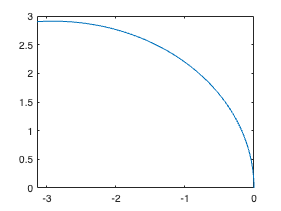

plot(X, Y);